## 使用1dfft数据测试呼吸率

离线测试

clc;clear;close all;
location = '6.30/';
file = '25s';
filename = [file, '.mat'];
load([location, filename]);
[FrameNum, ChirpNum, RxNum, SampleNum] = size(mergedData);

% 初始参数
p = setRadarParameters();
axis_info = setaxis(p);
axis_info.time = (1:FrameNum) * p.frameTime; 
% 裁剪
UsefulSampleNum = find(axis_info.range>p.rangecut, 1);
axis_info.range(UsefulSampleNum:end) = [];
UsefulChirpNumF = find(axis_info.velocity<-p.velocitycut, 1, 'last');
UsefulChirpNumL = find(axis_info.velocity>p.velocitycut, 1, "first");
axis_info.velocity([1:UsefulChirpNumF, UsefulChirpNumL:p.Chirps * p.Nfft]) = []; 

% 1dfft
ifft1dData = ifft(mergedData, [], 4);
fft1dData = fft1dwindow(ifft1dData, p.fft1dwindowType, p.Nfft);

1dfft done.


fft1dData(:,:,:,UsefulSampleNum:end) = [];
% MTI
MTIdata = MTI(fft1dData, p.MTIType);

Mean Cancellation done.


% 2dfft
fft2dData = fft2dwindow(MTIdata, p.fft2dwindowType, p.Nfft);

2dfft done.


fft2dData(:,[1:UsefulChirpNumF, UsefulChirpNumL:p.Chirps * p.Nfft],:,:) = [];
% NCA
NCAdata = squeeze(sum(fft2dData, 3));
% AAC
AACdata = applyAmplitudeCompensation(NCAdata);

AAC done.


% DN
DNdata = DenoisingRD(p.lossR, p.lossD, axis_info, AACdata); 

Denoising done.


% CFAR
cfarIdx = processCFARDetection(p.N_target, p.suppressWin, p.energyThresh, p.epsilon, p.minPts, DNdata); 

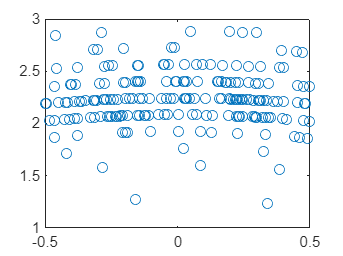

% DOA estimate
DoA = estimateDoA(cfarIdx, p, fft2dData);
% Position modeling
observations = PositionModel(cfarIdx, axis_info, DoA(:, 2));
observations = mutlpathfilt(observations, p);
figure;plot(observations(:,2), observations(:,3), 'o');xlim(p.x);ylim(p.y);

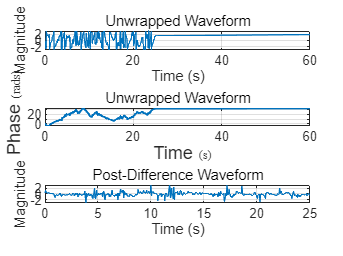

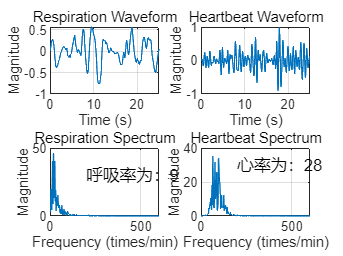

distanceIdx = round(mean(cfarIdx(:, 3)));
distanceIdx = 13;
rangeBin = fft1dData(:, 1, 2, distanceIdx);
[breathRate, heartRate,diff_ag] = get_heartBreath_rate(rangeBin, 1/p.frameTime);

% frameIdx =14
% fft1dData_test = db(squeeze(fft1dData(:, 1, 2, :)));
% plotRT(fft1dData_test, axis_info);title('fft1d data');
% mask = (fft1dData_test>30);
% MTIdata_test = db(squeeze(MTIdata(:, 1, 1, :)));
% plotRT(MTIdata_test, axis_info);title('MTI data');
% 
% fft2dData_test = db(squeeze(fft2dData(frameIdx, :, 1, :)));
% plotRV(fft2dData_test, axis_info);title('fft2d data');
% 
% NCAdata_test = db(squeeze(NCAdata(frameIdx, :, :)));
% plotRV(NCAdata_test, axis_info);title('NCAed Map');
% 
% AACdata_test = db(squeeze(AACdata(frameIdx, :, :)));
% plotRV(AACdata_test, axis_info);title('AACed Map');
% DNdata_test = db(squeeze(DNdata(frameIdx, :, :)));
% plotRV(DNdata_test, axis_info);title('Denoising data');